# Hyper-resistance group analyses

Fast Cyclic dorsiflexion + slow passive dorsiflexion tests.

Author: P Valadao pvaladao@tuta.io.

Last modified: 20/04/22.

PT_raw.mat: Peak torque in the common range of motion (16-3.5 degrees of plantarflexion) were analyzed with three offset criteria: 1) initial torque at the beggining of the trial; 2) torque right before pf movement started; 3) torque right before stretch started. There are 2 main trends: 1) neutral position has almost zero torque, and pf increases torque (weight of the foot); 2) neutral position has high torque (short MTU) and pf decreases torque. Thus for some participants like 5202/5108 (trend 2), the correct offset should be right before the stretch (ev3), the other 2 offsets produces negative values. For participants like 5207 (trend 1), the correct offset is either init or ev1, with offset ev3 giving negative values. Participants like 5214/5220 have negligigle torque during the stretch, so offset selection does not matter. Participants like 5106/5109 have very high torque values, and all offsets works well (they cause negligigle changes in such high values). The correct offset will be selected for each participant based on the torque behavior, some participants (5212,5214,5219,5220) had negligible torque in all offsets, thus their value was set to zero.

PT values have high CV, thus median will be utilized to summarize data.

## Peak torque @ 10 deg/s.

To allow comparison to the peak torque at 55 and 110 deg/s, peak torque was calculated until the end of the common range (4 deg of pf). This was necessary for the fast cyclic dorsiflexion test because of movement artefacts at the beggining and end of the stretch. Data is not normally distributed. 14 CP (5102 has not mechanical data) x 12 TD (5206,5210,5216 had inertial artefacts longer than the end of the common range.

load Passive_DF_all.mat
Flex_results = Flex_all(Flex_all.Subject ~= "5105",:); %exclude case study (5105)
ptcr_descriptives = groupsummary(Flex_results,"Group",{'mean','std','median','min','max','var'},'pt_10') 

ptcr_descriptives = 2×8 table
    Group    GroupCount       mean_pt_10          std_pt_10          median_pt_10           min_pt_10           max_pt_10           var_pt_10    
    _____    __________    ________________    ________________    _________________    _________________    ________________    ________________

     CP          14        3.31643605462467    3.61147123438124     2.02298796793912    0.173620423302054             13.5187    13.0427244767632
     TD          15        1.13378614720811    1.72880476880457    0.645909312879667    0.101278580259532    6.45392585429363    2.98876592864144


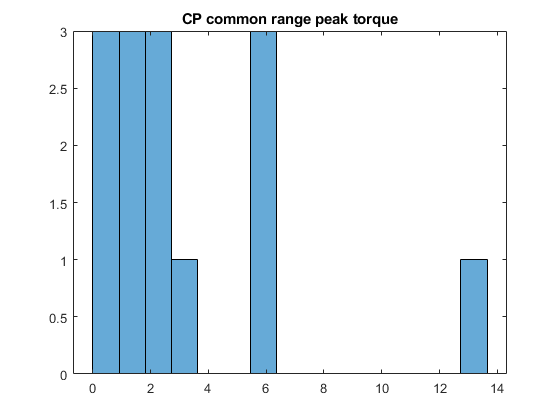

CP_pt10 = Flex_results.pt_10 (Flex_results.Group == "CP");
TD_pt10 = rmmissing(Flex_results.pt_10 (Flex_results.Group == "TD"));
histogram(CP_pt10,15),title('CP common range peak torque'),

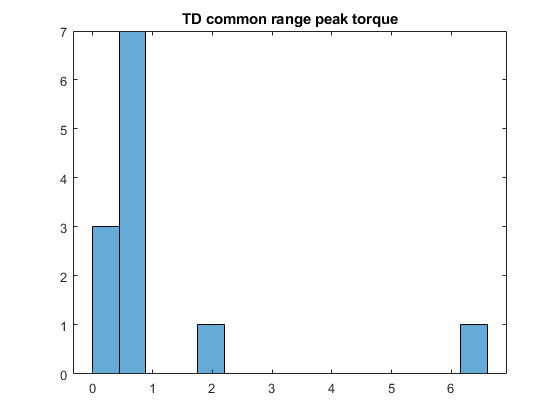

histogram(TD_pt10,15), title('TD common range peak torque'),

kurtosis_CP = kurtosis(CP_pt10)

kurtosis_CP =           5.51135663145481


kurtosis_TD = kurtosis(TD_pt10)

kurtosis_TD =           8.92678116114128


skewness_CP = skewness(CP_pt10)

skewness_CP =           1.72662461481247


skewness_TD = skewness(TD_pt10)

skewness_TD =           2.71338706291659


normalitytest(CP_pt10'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.9980 	     0.2722                 1 
KS Stephens Modification       1.0559 	     0.0100                 0 
KS Marsaglia Method            0.9980 	     0.2276                 1 
KS Lilliefors Modification     0.2667 	     0.0079                 0 
Anderson-Darling Test          1.1950 	     0.0052                 0 
Cramer- Von Mises Test         0.1980 	     0.0057                 0 
Shapiro-Wilk Test              0.7777 	     0.0027                 0 
Shapiro-Francia Test           0.7649 	     0.0027                 0 
Jarque-Bera Test               10.6352 	     0.0049                 0 
DAgostino & Pearson Test       14.7587 	     0.0006                 0 


normalitytest(TD_pt10');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.4151 	     0.0364                 0 
KS Stephens Modification       1.5112 	     0.0100                 0 
KS Marsaglia Method            1.4151 	     0.0253                 0 
KS Lilliefors Modification     0.4085 	     0.0000                 0 
Anderson-Darling Test          2.6161 	     0.0000                 0 
Cramer- Von Mises Test         0.4811 	     0.0000                 0 
Shapiro-Wilk Test              0.5268 	     0.0000                 0 
Shapiro-Francia Test           0.4955 	     0.0000                 0 
Jarque-Bera Test               32.2883 	     0.0000                 0 
DAgostino & Pearson Test       29.3162 	     0.0000                 0 


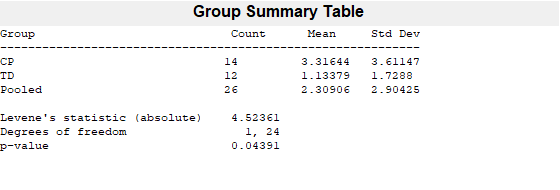

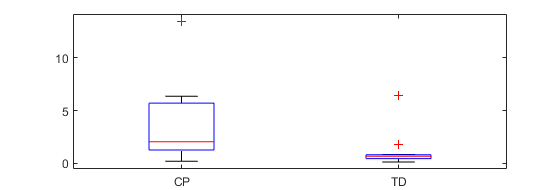

p =         0.0439079448071292


p = vartestn(Flex_results.pt_10,Flex_results.Group,'TestType','LeveneAbsolute')

p = vartestn(Flex_results.pt_10,Flex_results.Group,'TestType','LeveneQuadratic','display','off')

p =           0.25416002056545


[p,h,stats] = ranksum(CP_pt10,TD_pt10) %Wilcoxon rank sum test

p =          0.042188009531505


h = logical
   1


stats = struct with fields:
       zval: 2.03166077450088
    ranksum: 229


median(CP_pt10)

ans =           2.02298796793912


iqr(CP_pt10)

ans =           4.45935789612122


median(TD_pt10)

ans =          0.645909312879667


iqr(TD_pt10)

ans =          0.363259397563525


## Peak torque @ 55 deg/s.

13CP, 14TD. TD data is not normal, groups have unequal variances.

5102 due to heel, 5113/5219 due to mechanical artefact.

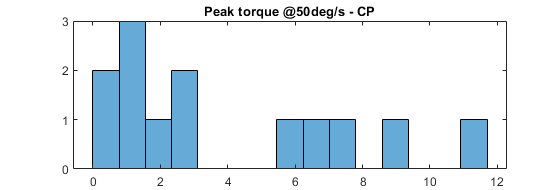

load PT_processed.mat
CP_pt55 = pt.pt50(pt.Group == "CP");
TD_pt55 = pt.pt50(pt.Group == "TD");
histogram(CP_pt55,15),title('Peak torque @50deg/s - CP'),

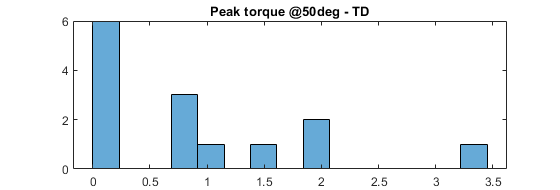

histogram(TD_pt55,15),title('Peak torque @50deg - TD'),

kurtosis_CP = kurtosis(CP_pt55)

kurtosis_CP =           2.43293483122185


kurtosis_TD = kurtosis(TD_pt55)

kurtosis_TD =           3.26988731757733


skewness_CP = skewness(CP_pt55)

skewness_CP =          0.790965067574723


skewness_TD = skewness(TD_pt55)

skewness_TD =           1.04477931230051


normalitytest(CP_pt55');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.8028 	     0.5396                 1 
KS Stephens Modification       0.8531 	     0.0776                 1 
KS Marsaglia Method            0.8028 	     0.4728                 1 
KS Lilliefors Modification     0.2227 	     0.0774                 1 
Anderson-Darling Test          0.6734 	     0.0516                 1 
Cramer- Von Mises Test         0.1144 	     0.0714                 1 
Shapiro-Wilk Test              0.8836 	     0.0797                 1 
Shapiro-Francia Test           0.8920 	     0.0929                 1 
Jarque-Bera Test               1.5297 	     0.4654                 1 
DAgostino & Pearson Test       2.1873 	     0.3350                 1 


normalitytest(TD_pt55');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7805 	     0.5762                 1 
KS Stephens Modification       0.8258 	     0.0956                 1 
KS Marsaglia Method            0.7805 	     0.5105                 1 
KS Lilliefors Modification     0.2086 	     0.1001                 1 
Anderson-Darling Test          0.8325 	     0.0257                 0 
Cramer- Von Mises Test         0.1259 	     0.0499                 0 
Shapiro-Wilk Test              0.8458 	     0.0195                 0 
Shapiro-Francia Test           0.8498 	     0.0232                 0 
Jarque-Bera Test               2.5895 	     0.2740                 1 
DAgostino & Pearson Test       4.7687 	     0.0921                 1 


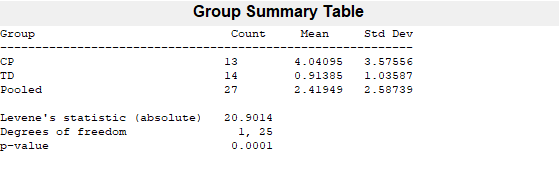

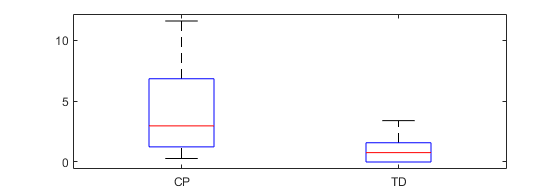

p =       0.000113058272913482


p = vartestn(pt.pt50,pt.Group,'TestType','LeveneAbsolute')

p = vartestn(pt.pt50,pt.Group,'TestType','LeveneQuadratic','display','off')

p =         0.0112444847735801


[p,h,stats] = ranksum(CP_pt55,TD_pt55) %Wilcoxon rank sum test

p =        0.00519764198659444


h = logical
   1


stats = struct with fields:
       zval: 2.79452252394232
    ranksum: 240


median(CP_pt55)

ans =           2.97260658142227


iqr(CP_pt55)

ans =           5.60346341993909


median(TD_pt55)

ans =          0.768967963358622


iqr(TD_pt55)

ans =           1.58528995654952


## Peak torque @ 110 deg/s.

Normal distribution, unequal variances in groups.

5102 due to heel, 5113/5219 due to mechanical artefact.

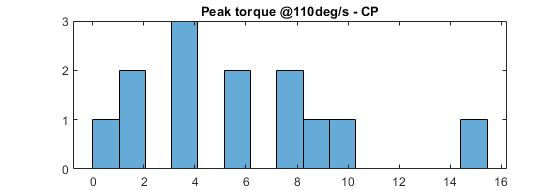

CP_pt110 = pt.pt100(pt.Group == "CP");
TD_pt110 = pt.pt100(pt.Group == "TD");
histogram(CP_pt110,15),title('Peak torque @110deg/s - CP'),

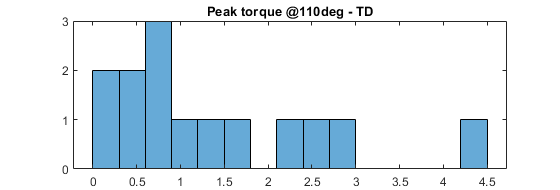

histogram(TD_pt110,15),title('Peak torque @110deg - TD'),

kurtosis_CP = kurtosis(CP_pt110)

kurtosis_CP =           3.41701850351336


kurtosis_TD = kurtosis(TD_pt110)

kurtosis_TD =           3.36053671322454


skewness_CP = skewness(CP_pt110)

skewness_CP =          0.894823811367878


skewness_TD = skewness(TD_pt110)

skewness_TD =           1.07268155902208


normalitytest(CP_pt110');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5086 	     0.9581                 1 
KS Stephens Modification       0.5405 	     0.1500                 1 
KS Marsaglia Method            0.5086 	     0.9262                 1 
KS Lilliefors Modification     0.1411 	     0.2000                 1 
Anderson-Darling Test          0.3864 	     0.3899                 1 
Cramer- Von Mises Test         0.0488 	     0.5269                 1 
Shapiro-Wilk Test              0.9206 	     0.2556                 1 
Shapiro-Francia Test           0.9164 	     0.1910                 1 
Jarque-Bera Test               1.8291 	     0.4007                 1 
DAgostino & Pearson Test       4.0914 	     0.1293                 1 


normalitytest(TD_pt110');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7753 	     0.5847                 1 
KS Stephens Modification       0.8203 	     0.0991                 1 
KS Marsaglia Method            0.7753 	     0.5187                 1 
KS Lilliefors Modification     0.2072 	     0.1055                 1 
Anderson-Darling Test          0.7298 	     0.0403                 0 
Cramer- Von Mises Test         0.1236 	     0.0536                 1 
Shapiro-Wilk Test              0.8803 	     0.0587                 1 
Shapiro-Francia Test           0.8773 	     0.0509                 1 
Jarque-Bera Test               2.7607 	     0.2515                 1 
DAgostino & Pearson Test       5.1276 	     0.0770                 1 


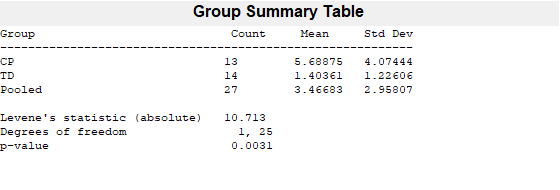

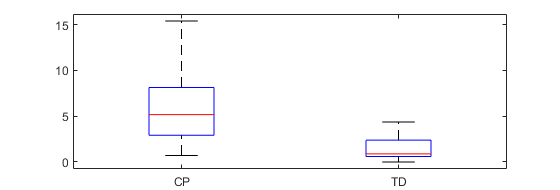

p =        0.00310496057700699


p = vartestn(pt.pt100,pt.Group,'TestType','LeveneAbsolute')

p = vartestn(pt.pt100,pt.Group,'TestType','LeveneQuadratic','display','off')

p =         0.0463888376020578


[h,p,ci,stats] = ttest2(CP_pt110,TD_pt110,"Vartype","unequal")

h =      1


p =        0.00266371335289739


ci =           1.76178076793733
          6.80849463409486


stats = struct with fields:
    tstat: 3.64197622861225
       df: 14.0113811756432
       sd: [2×1 double]


%pwrout_pt100 = sampsizepwr('t2',[5.69,4.1], 1.4 ,[],13, "Ratio",1.0769)
es_pt100 = mes(CP_pt110,TD_pt110,'hedgesg','exactCi',true) %hedge´s g

es_pt100 = struct with fields:
            isDep: 0
            nBoot: 0
        confLevel: 0.95
                n: [2×1 double]
                t: [1×1 struct]
          hedgesg: 1.40472661575457
        hedgesgCi: [2×1 double]
    hedgesgCiType: 'exact analytical'


%[p,h,stats] = ranksum(CP_pt110,TD_pt110) %Wilcoxon rank sum test
%median(CP_pt110)
%iqr(CP_pt110)
%median(TD_pt110)
%iqr(TD_pt110)

## Effects of velocity

within group effect of stretch velocity on peak torque in the common range.

Remove all subjects without data in all three velocities. 13 CP, 11 TD.

pt_vel = Flex_results(:,[1:2,16]);
pt_vel = outerjoin(pt_vel,pt(:,[1,3:4]),'Keys',{'Subject'},'MergeKeys',true);
pt_vel = rmmissing(pt_vel);
vel_cp = table2array(pt_vel(pt_vel.Group == "CP",[3:5]));
vel_td = table2array(pt_vel(pt_vel.Group == "TD",[3:5]));
% effects of velocity in CP
[p,tbl,stats] = friedman(vel_cp, 1,'on')

p =       0.000911881965554516


tbl = 4×6 cell array
    {'Source' }    {'SS'}    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'         }
    {'Columns'}    {[14]}    {[ 2]}    {[       7]}    {[      14]}    {[0.000911881965554516]}
    {'Error'  }    {[12]}    {[24]}    {[     0.5]}    {0×0 double}    {0×0 double            }
    {'Total'  }    {[26]}    {[38]}    {0×0 double}    {0×0 double}    {0×0 double            }


stats = struct with fields:
       source: 'friedman'
            n: 13
    meanranks: [1.6154 1.5385 2.8462]
        sigma: 1


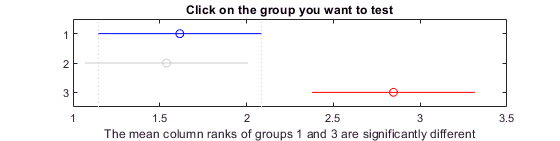

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


c =     1.0000    2.0000   -0.8621    0.0769    1.0159    1.0000
    1.0000    3.0000   -2.1698   -1.2308   -0.2918    0.0051
    2.0000    3.0000   -2.2467   -1.3077   -0.3687    0.0026


m =     1.6154    0.2774
    1.5385    0.2774
    2.8462    0.2774


h =   Figure (9: Multiple comparison of mean column ranks) with properties:

      Number: 9
        Name: 'Multiple comparison of mean column ranks'
       Color: [0.9400 0.9400 0.9400]
    Position: [681 838.2000 560 140.8000]
       Units: 'pixels'

  Show all properties


gnames = 3×1 char array
    '1'
    '2'
    '3'


[c,m,h,gnames] = multcompare(stats,'CType','bonferroni')

median(vel_cp(:,1))

ans = 2.0907

iqr(vel_cp(:,1))

ans = 4.4116

median(vel_cp(:,2))

ans = 2.9726

iqr(vel_cp(:,2))

ans = 5.6035

median(vel_cp(:,3))

ans = 5.1719

iqr(vel_cp(:,3))

ans = 5.2151

%effects of velocity in TD
[p,tbl,stats] = friedman(vel_td, 1,'on')

p = 0.1150

tbl = 4×6 cell array
    {'Source' }    {'SS'     }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Columns'}    {[ 4.2273]}    {[ 2]}    {[  2.1136]}    {[  4.3256]}    {[     0.1150]}
    {'Error'  }    {[17.2727]}    {[20]}    {[  0.8636]}    {0×0 double}    {0×0 double   }
    {'Total'  }    {[21.5000]}    {[32]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       source: 'friedman'
            n: 11
    meanranks: [2.1818 1.5000 2.3182]
        sigma: 0.9886


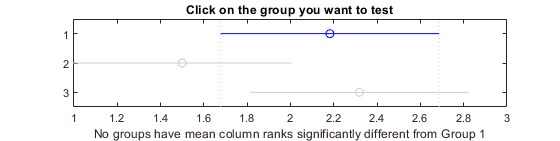

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


c =     1.0000    2.0000   -0.3273    0.6818    1.6909    0.3173
    1.0000    3.0000   -1.1455   -0.1364    0.8728    1.0000
    2.0000    3.0000   -1.8273   -0.8182    0.1909    0.1568


m =     2.1818    0.2981
    1.5000    0.2981
    2.3182    0.2981


h =   Figure (10: Multiple comparison of mean column ranks) with properties:

      Number: 10
        Name: 'Multiple comparison of mean column ranks'
       Color: [0.9400 0.9400 0.9400]
    Position: [681 838.2000 560 140.8000]
       Units: 'pixels'

  Show all properties


gnames = 3×1 char array
    '1'
    '2'
    '3'


[c,m,h,gnames] = multcompare(stats,'CType','bonferroni')

median(vel_td(:,1))

ans = 0.6469

iqr(vel_td(:,1))

ans = 0.4524

median(vel_td(:,2))

ans = 0.7520

iqr(vel_td(:,2))

ans = 1.4486

median(vel_td(:,3))

ans = 0.7351

iqr(vel_td(:,3))

ans = 1.5868